clear; clc;
syms t T n
omega = 2*pi/T;
Bn = 2/T*int(t*sin(n*omega*t), t, -T/2, T/2);
Bn = simplify(Bn)

$$Bn = \frac{T\,\left(\sin\left(\pi \,n\right)-\pi \,n\,\cos\left(\pi \,n\right)\right)}{n^{2}\,\pi^{2}}$$

subs(Bn, T, 4)

$$ans = \frac{4\,\left(\sin\left(\pi \,n\right)-\pi \,n\,\cos\left(\pi \,n\right)\right)}{n^{2}\,\pi^{2}}$$

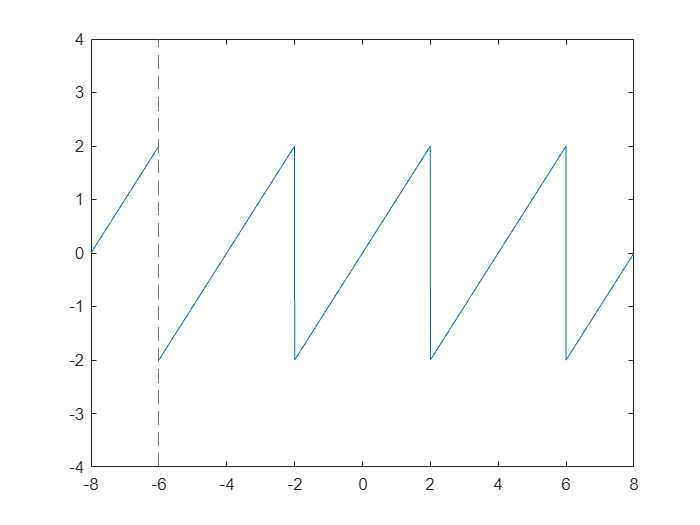

clear; clc;
T = 4;
f = @(t) mod(t-T/2, T) - T/2;
fplot(f, [-2*T, 2*T]);
xlim([-2*T, 2*T]);
ylim([-T, T]);

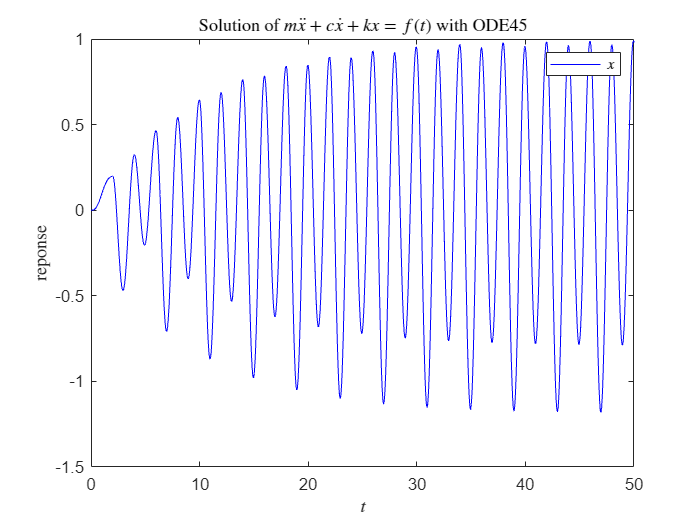

m = 1;
c = 0.2;
k = 10;
time_span = [0, 50];
x_init = [
    0; 
    0];
[t,x] = ode45(@(t, x) vdp1(t, x, f, m, c, k), time_span, x_init);
plot(t,x(:,1),'-b')
title('Solution of $m \ddot x + c \dot x + k x = f(t)$ with ODE45', 'Interpreter','Latex');
xlabel('$t$', 'Interpreter','Latex');
ylabel('reponse', 'Interpreter','Latex');
legend('$x$', 'Interpreter','Latex');

function dydt = vdp1(t, x, f, m, c, k)
  dydt = [
      x(2); 
      (f(t) - c*x(2) - k*x(1))/m];
end
